clear;

## Question 4

moler #11.5

fTest = @(x,y) 0*x + 0*y - 1;
uTrue = @(x,y) -1/4*(x.^2 + y.^2);

xMin = -3; xMax = 3;

n = 25;
h = (xMax - xMin) / (n+1);
x = xMin+h : h : xMax-h;
[X,Y] = meshgrid(x,x);
Z = fTest(X,Y);
% Z = peaks(X,Y);
F = h^2*Z(:);

I = eye(n);
c = [-2 1 zeros(1,n-2)];
D = toeplitz(c);
D = kron(D,I) + kron(I,D);
det(D)

ans = -Inf

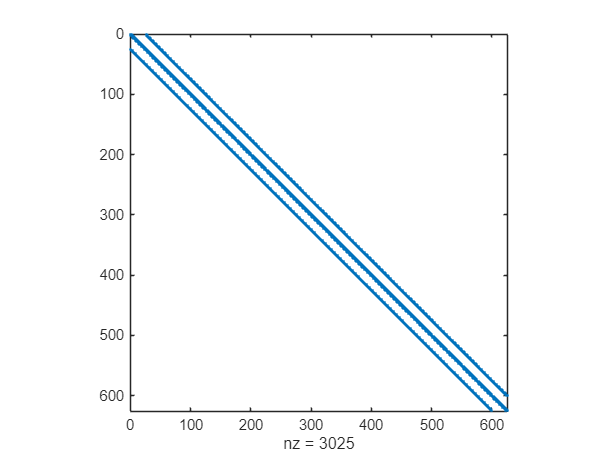


figure();
spy(D)


U = D \ F;

%tiledlayout(1,2);

%nexttile;
%surf(X, Y, reshape(U, [n,n]))
%nexttile;
%surf(X, Y, uTrue(X,Y))

% spy(A)
% I = speye(n,n);
% E = sparse(2:n, 1:n-1, 1, n, n);
% D = E+E'-2*I;
% A = kron(D,I)+kron(I,D);
% spy(A)

## (a)

## (b)

## (c)

## (d)

function p = peaksSource(x,y)

[X,Y] = meshgrid(x,y);
p = peaks(X,Y);

end